# PN-Kompensation für schwach gedämpftes PT2 System

s = tf('s');
w0 = 4; D= 0.2; K = 0.25

K = 0.2500

G = K*w0^2/(s^2 + 2*D*w0*s + w0^2)


G =
 
         4
  ----------------
  s^2 + 1.6 s + 16
 
Continuous-time transfer function.



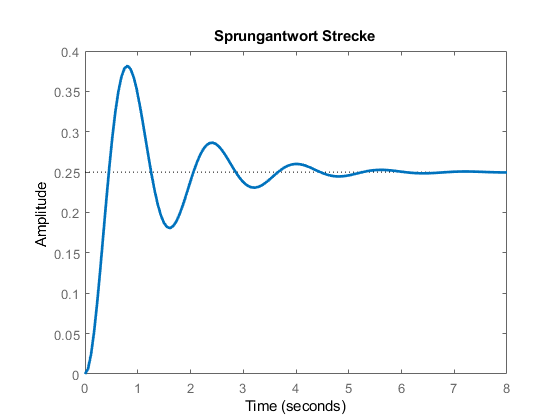

step(G)
h = gca; h.Children(1).Children(2).LineWidth =2;
title('Sprungantwort Strecke')

## Regler


Kp = 1.55;
R = Kp *(s^2 + 2*D*w0*s + w0^2)/(s*(0.05*s+1))


R =
 
  1.55 s^2 + 2.48 s + 24.8
  ------------------------
        0.05 s^2 + s
 
Continuous-time transfer function.



L = minreal(G*R);

% Führungsübertragung
T = minreal(L/(1+L))


T =
 
        124
  ----------------
  s^2 + 20 s + 124
 
Continuous-time transfer function.



% Eigenschaften des geschlossenen Kreises
% stationäre Übertragung
K_grk = dcgain(T)

K_grk = 1.0000

% dynmische Eigenschaften:
damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e+01 + 4.90e+00i     8.98e-01       1.11e+01         1.00e-01    
 -1.00e+01 - 4.90e+00i     8.98e-01       1.11e+01         1.00e-01    


## Zeitsimualtion Führungsübertragung

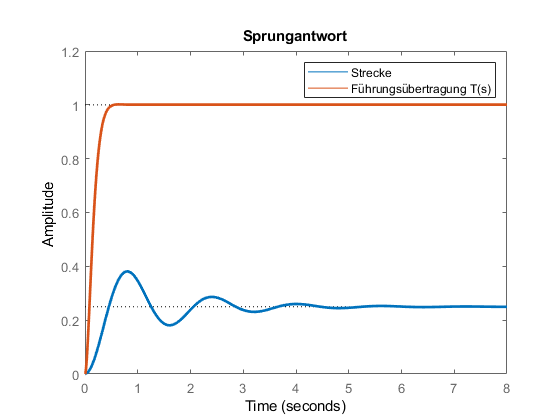

step(G,T)
h = gca;
lines = findobj(gcf,'Type','Line'); set(lines,'Linewidth',2);
title('Sprungantwort')
legend('Strecke','Führungsübertragung T(s)')

## Zeitsimualtion Störsensitivität

GS = minreal(G/(1+L))


GS =
 
                4 s^2 + 80 s
  -----------------------------------------
  s^4 + 21.6 s^3 + 172 s^2 + 518.4 s + 1984
 
Continuous-time transfer function.



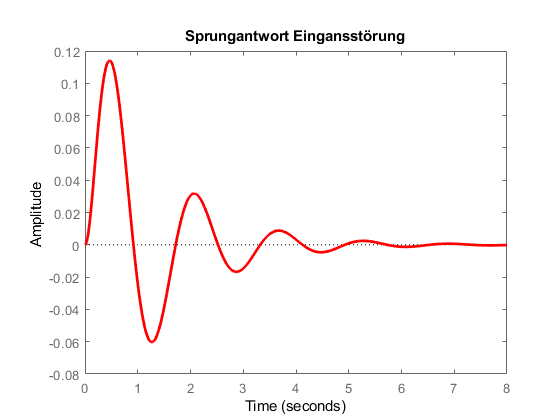

step(GS,'r')
h = gca; h.Children(1).Children(2).LineWidth =2;
title('Sprungantwort Eingansstörung')

## Schwingungsfähiges Verhalten bleibt im Störkanal erhalten!